clear all
clc
syms x1(t) x2(t) y1(t) y2(t) theta1(t) theta2(t) F1x(t) F1y(t) F2x(t) F2y(t) F3x(t) F3y(t)

animate_it = 1;     % set to 1 to plot the animation
save_it = 0;        % set to 1 to save the animation

m1=4; m2=2;L=3; 

IG1=1/12*m1*L^2; IG2=1/12*m2*L^2;

rG1=[x1(t);y1(t)];
rG2=[x2(t);y2(t)];
F1=[F1x(t);F1y(t)];
F2=[F2x(t);F2y(t)];
F3=[F3x(t);F3y(t)];
g=9.81;

%Forces 1 and 2 act on the top arm, Force 3 on the bottom arm. 

%F=ma for top arm
eq1=m1*diff(rG1,t,t)==F1+F2-m1*g*[0;1];
MF1G1=cross(-[rG1;0],[F1;0]);
MF2G1=cross([rG1;0],[F2;0]);
%IG theta''=M for the top arm
eq2=IG1*diff(theta1(t),t,t)==MF1G1(3)+MF2G1(3);

%F=ma for the bottom arm.
eq3=m2*diff(rG2,t,t)==F3-m2*g*[0;1];
%IG theta''=M for the bototm.
MF3G2=cross(L/2*[-sin(theta2(t));cos(theta2(t));0],[F3;0]);
eq4=IG2*diff(theta2(t),t,t)==MF3G2(3);

%Keep top arm anchored at origin. 
eq5=rG1+L/2*[-sin(theta1(t));cos(theta1(t))]==[0;0];
%Keep top arm and bottom arm attached. 
eq6=rG1+L/2*[sin(theta1(t));-cos(theta1(t))]==rG2+L/2*[-sin(theta2(t));cos(theta2(t))];
%F2 and F3 must be related. 
eq7=F2==-F3;

DES=[eq1;eq2;eq3;eq4;eq7];
disp_const=[eq5;eq6];
vel_const = [];


The unknown functions (just the base functions, not derivatives) are: F1x(t),F2x(t),F3x(t),F1y(t),F2y(t),F3y(t),theta1(t),theta2(t),x1(t),x2(t),y1(t),y2(t)
Initial Conditions:
Y0/YP0:
F1x: -7.500000 F1xt:0.000000
F2x: 1.500000 F2xt:0.000000
F3x: -1.500000 F3xt:0.000000
F1y: 11.772000 F1yt:0.000000
F2y: 3.924000 F2yt:0.000000
F3y: -3.924000 F3yt:0.000000
theta1: 1.570796 theta1t:1.000000
theta2: 0.000000 theta2t:0.000000
x1: 1.500000 x1t:0.000000
x2: 3.000000 x2t:0.000000
y1: 0.000000 y1t:1.500000
y2: -1.500000 y2t:3.000000
Dtheta1t: 1.000000 Dtheta1tt:-3.924000
Dtheta2t: 0.000000 Dtheta2tt:1.500000
Dx1t: 0.000000 Dx1tt:-1.500000
Dx2t: 0.000000 Dx2tt:-0.750000
Dy1t: 1.500000 Dy1tt:-5.886000
Dy2t: 3.000000 Dy2tt:-11.772000


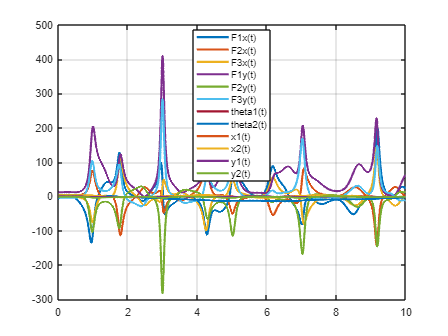


soln=mechanicsAsDAE(DES,disp_const,vel_const,[0 10],{theta1==pi/2,theta2==0,diff(theta1)==1,diff(theta2)==0});

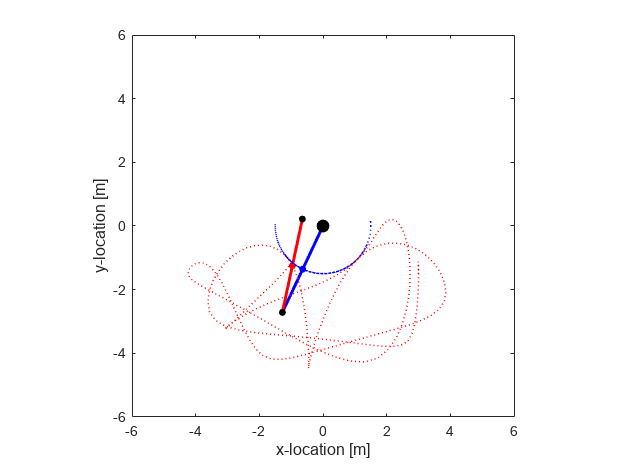

if animate_it == 1
    t_anim = linspace(min(soln.t),max(soln.t),201)';
    theta1_anim = interp1(soln.t,soln.theta1,t_anim);
    theta2_anim = interp1(soln.t,soln.theta2,t_anim);
    func_animate_double_pendulum(t_anim,theta1_anim,theta2_anim,L,L,save_it)
end

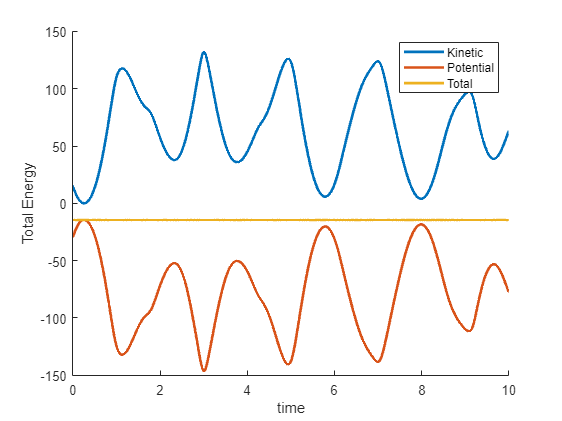

KineticEnergy=1/2*m1*(soln.Dx1t.^2+soln.Dy1t.^2)+1/2*m2*(soln.Dx2t.^2+soln.Dy2t.^2)...
    +1/2*IG1*soln.Dtheta1t.^2+1/2*IG2*soln.Dtheta2t.^2;
PotentialEnergy=m1*soln.y1*g+m2*soln.y2*g;
figure
clf
hold on
plot(soln.t,KineticEnergy,'LineWidth',2)
plot(soln.t,PotentialEnergy,'LineWidth',2)
plot(soln.t,KineticEnergy+PotentialEnergy,'LineWidth',2)
xlabel('time'); ylabel('Total Energy')
legend('Kinetic','Potential','Total')

function [] = func_animate_double_pendulum(t,theta1,theta2,L1,L2,save_it)

skip_frame = 1;

if save_it == 1
    %--------------------------------------------------------------------------
    % animate the results
    saveDirName = uigetdir('', ['Specify the directory where the ', ...
        'animations will be saved.']);

    %  Append a slash to the directory name ('/' for Mac, '\' for Windows):
    if isempty(strfind(saveDirName, '/')) == 0
        saveDirName = [saveDirName, '/'];
    else
        saveDirName = [saveDirName, '\'];
    end

    animObj = VideoWriter([saveDirName, 'double_pendulum.avi']);
    open(animObj)
    skip_frame = 5;
end

% plot the angular displacements
figure(1)
clf
plot(0,0)
xlabel('x-location [m]')
ylabel('y-location [m]')
axis equal
axis([-(L1+L2) (L1+L2) -(L1+L2) (L1+L2)])

for k = 1:length(t)

    R_a_I = [sin(theta1(k)) cos(theta1(k)) 0;-cos(theta1(k)) sin(theta1(k)) 0;0 0 1];
    R_b_I = [sin(theta2(k)) cos(theta2(k)) 0;-cos(theta2(k)) sin(theta2(k)) 0;0 0 1];

    rAx(k,1) = 0;
    rAy(k,1) = 0;

    temp = R_a_I*[L1/2;0;0];
    rG1x(k,1) = temp(1);
    rG1y(k,1) = temp(2);

    temp = R_a_I*[L1;0;0];
    rBx(k,1) = temp(1);
    rBy(k,1) = temp(2);

    temp = R_a_I*[L1;0;0] + R_b_I*[L2/2;0;0];
    rG2x(k,1) = temp(1);
    rG2y(k,1) = temp(2);

    temp = R_a_I*[L1;0;0] + R_b_I*[L2;0;0];
    rCx(k,1) = temp(1);
    rCy(k,1) = temp(2);
end

%  Draw pendulums, joints, and CGs
pend1 = line('xdata', [rAx(1) rBx(1)], 'ydata', [rAy(1) rBy(1)],...
    'color','b','linewidth',2);
pend2 = line('xdata', [rBx(1) rCx(1)], 'ydata', [rBy(1) rCy(1)],...
    'color','r','linewidth',2);
pointA = line('xdata', rAx(1), 'ydata', rAy(1), ...
    'marker', 'o', 'color', 'k', 'markerfacecolor', 'k', 'markersize', 8);
pointB = line('xdata', rBx(1), 'ydata', rBy(1), ...
    'marker', 'o', 'color', 'k', 'markerfacecolor', 'k', 'markersize', 4);
pointC = line('xdata', rCx(1), 'ydata', rCy(1), ...
    'marker', 'o', 'color', 'k', 'markerfacecolor', 'k', 'markersize', 4);
pointG1 = line('xdata', rG1x(1), 'ydata', rG1y(1), ...
    'marker', 'o', 'color', 'b', 'markerfacecolor', 'b', 'markersize', 4);
pointG2 = line('xdata', rG2x(1), 'ydata', rG2y(1), ...
    'marker', 'o', 'color', 'r', 'markerfacecolor', 'r', 'markersize', 4);
pathG1 = line('xdata', rG1x(1:1), 'ydata', rG1y(1:1), ...
    'color', 'b', 'linewidth', 1, 'linestyle',':');
pathG2 = line('xdata', rG2x(1:1), 'ydata', rG2y(1:1), ...
    'color', 'r', 'linewidth', 1, 'linestyle',':');


for k = 1:skip_frame:length(t)
    set(pend1, 'xdata', [rAx(k) rBx(k)], 'ydata', [rAy(k) rBy(k)]);
    set(pend2, 'xdata', [rBx(k) rCx(k)], 'ydata', [rBy(k) rCy(k)]);
    set(pointB,'xdata', rBx(k), 'ydata', rBy(k));
    set(pointC,'xdata', rCx(k), 'ydata', rCy(k));
    set(pointG1,'xdata', rG1x(k), 'ydata', rG1y(k));
    set(pointG2,'xdata', rG2x(k), 'ydata', rG2y(k));
    set(pathG1,'xdata', rG1x(1:k), 'ydata', rG1y(1:k));
    set(pathG2,'xdata', rG2x(1:k), 'ydata', rG2y(1:k));
    drawnow

    if save_it == 1
        writeVideo(animObj, getframe(gcf));
    end
end

if save_it == 1
    close(animObj)
end
end
